# Homework 6

## [✔] ADSI Problem 4.7: Coherence function

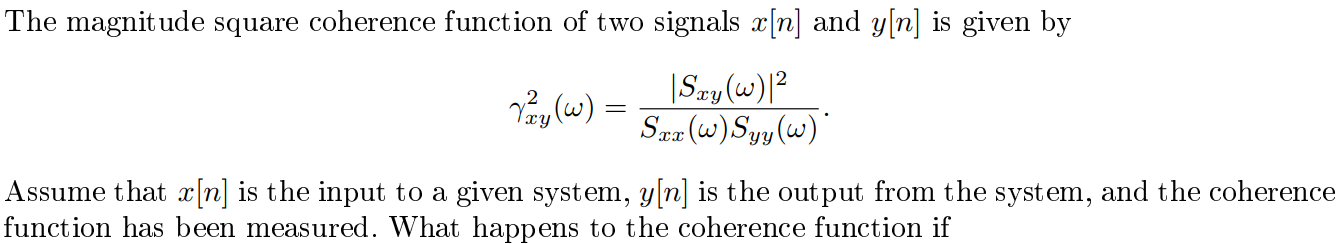

### 1) What happens to the coherence function if gain is increased from 1 to 2:

To answer this question, we need to compute the new coherence function. Power Spectral Density $S_x \left(\omega \right)$ and Cross-Power Spectral Density $S_{\mathrm{yx}} \left(\omega \right)$ are essentially the discrete-time Fourier Transform of the corresponding auto-correlation and cross-correlation.

So we need to compute those first. The autocorrelation for the input signal is the same because the input signal has not changed. We need to compute the autocorrelation for the new output signal.

Let $z\left(n\right)=2y\left(n\right)$ denote the new output signal.

The autocorrelation for the new output signal $r_z \left(\ell \right)$ can be computed as follows:

        
$$r_z \left(\ell \right)=E\left\lbrack z\left(n\right)z\left(n-\ell \right)\right\rbrack$$


        
$$r_z \left(\ell \right)=E\left\lbrack 2y\left(n\right)2y\left(n-\ell \right)\right\rbrack$$


        
$$r_z \left(\ell \right)=4E\left\lbrack y\left(n\right)y\left(n-\ell \right)\right\rbrack$$


        
$$r_z \left(\ell \right)=4r_y \left(\ell \right)$$


To find the PSD, we take the Fourier Transform:

        
$$S_z \left(\omega \right)=R_z \left(e^{j\omega } \right)=4R_y \left(e^{j\omega } \right)=4S_y \left(\omega \right)$$


This means that if the output gain is increased by 2, the PSD increases by a factor of 4.

Next, we need compute the cross-correlation $r_{\mathrm{zx}} \left(\ell \right)$:

        
$$r_{\mathrm{zx}} \left(\ell \right)=E\left\lbrack z\left(n\right)x\left(n-\ell \right)\right\rbrack$$


        
$$r_{\textrm{zx}} \left(\ell \right)=E\left\lbrack 2y\left(n\right)x\left(n-\ell \right)\right\rbrack$$


        
$$r_{\textrm{zx}} \left(\ell \right)=2E\left\lbrack y\left(n\right)x\left(n-\ell \right)\right\rbrack$$


        
$$r_{\textrm{zx}} \left(\ell \right)=2r_{\mathrm{yx}} \left(\ell \right)$$


To find the PSD, we take the Fourier Transform:

        
$$S_{\mathrm{zx}} \left(\omega \right)=R_{\mathrm{zx}} \left(e^{j\omega } \right)=2R_{\mathrm{yx}} \left(e^{j\omega } \right)=2S_{\mathrm{yx}} \left(\omega \right)$$


Finally, we can compute the coherence function:

        
$${\left|\gamma_{\textrm{zx}} \left(\omega \right)\right|}^2 =\frac{{\left|S_{\textrm{zx}} \left(\omega \right)\right|}^2 }{S_z \left(\omega \right)S_{\textrm{x}} \left(\omega \right)}$$

$$=\frac{{\left|2S_{\textrm{yx}} \left(\omega \right)\right|}^2 }{4S_y \left(\omega \right)S_{\mathrm{x}} \left(\omega \right)}$$

$$=\frac{{\left|2\right|}^2 {\left|S_{\textrm{yx}} \left(\omega \right)\right|}^2 }{4S_y \left(\omega \right)S_{\mathrm{x}} \left(\omega \right)}$$

$$=\frac{{\left|S_{\textrm{yx}} \left(\omega \right)\right|}^2 }{S_y \left(\omega \right)S_{\mathrm{x}} \left(\omega \right)}$$


The coherence function with the new output signal is the same the original coherence function.

This means that increasing the output gain by 2, nothing happens to the coherence function.

### 2) What happens to the coherence function if a delay happens in the measurement?

Let $z\left(n\right)=y\left(n-D\right)$

First, compute the autocorrelation for the new output signal $r_z \left(\ell \right)$:

        
$$r_z \left(\ell \right)=E\left\lbrack y\left(n-D\right)y\left(n-D-\ell \right)\right\rbrack$$


Let $m=n-D$ then we can write the above equation as:

        
$$r_z \left(\ell \right)=E\left\lbrack y\left(m\right)y\left(m-\ell \right)\right\rbrack$$
  

This expression is the same as $r_y \left(\ell \right)$ so the delayed output signal does not change the autocorrelation:

        
$$r_z \left(\ell \right)=r_y \left(\ell \right)$$


Next, we compute the cross-correlation:

        
$$r_{\mathrm{zx}} \left(\ell \right)=E\left\lbrack z\left(n\right)x\left(n-\ell \right)\right\rbrack$$


        
$$r_{\textrm{zx}} \left(\ell \right)=E\left\lbrack y\left(n-D\right)x\left(n-\ell \right)\right\rbrack$$


        
$$r_{\textrm{zx}} \left(\ell \right)=E\left\lbrack y\left(n\right)x\left(n-\ell +D\right)\right\rbrack$$


        
$$r_{\textrm{zx}} \left(\ell \right)=r_{\mathrm{yx}} \left(\ell +D\right)$$


To find the Fourier Transform, we can use the Fourier pair: $f\left(t-t_0 \right)\leftrightarrow F\left(e^{j\omega \;} \right)e^{-j\omega t_0 }$

        
$$R_{\mathrm{zx}} \left(e^{j\omega } \right)=R_{\mathrm{yx}} \left(e^{j\omega } \right)e^{j\omega D} =S_{\mathrm{yx}} \left(\omega \right)e^{j\omega D}$$


Finally, we can compute the coherence function:

        
$${\left|\gamma_{\textrm{zx}} \left(\omega \right)\right|}^2 =\frac{{\left|S_{\textrm{zx}} \left(\omega \right)\right|}^2 }{S_z \left(\omega \right)S_{\textrm{x}} \left(\omega \right)}$$

$$=\frac{{\left|e^{j\omega D} S_{\textrm{yx}} \left(\omega \right)\right|}^2 }{S_y \left(\omega \right)S_{\mathrm{x}} \left(\omega \right)}$$

$$=\frac{{\left|e^{j\omega D} \right|}^2 \;{\left|S_{\textrm{yx}} \left(\omega \right)\right|}^2 \;}{S_y \left(\omega \right)S_{\mathrm{x}} \left(\omega \right)}$$


The norm of the $e^{j\omega D}$ is 1 because this quantity describes a point on the unit circle:

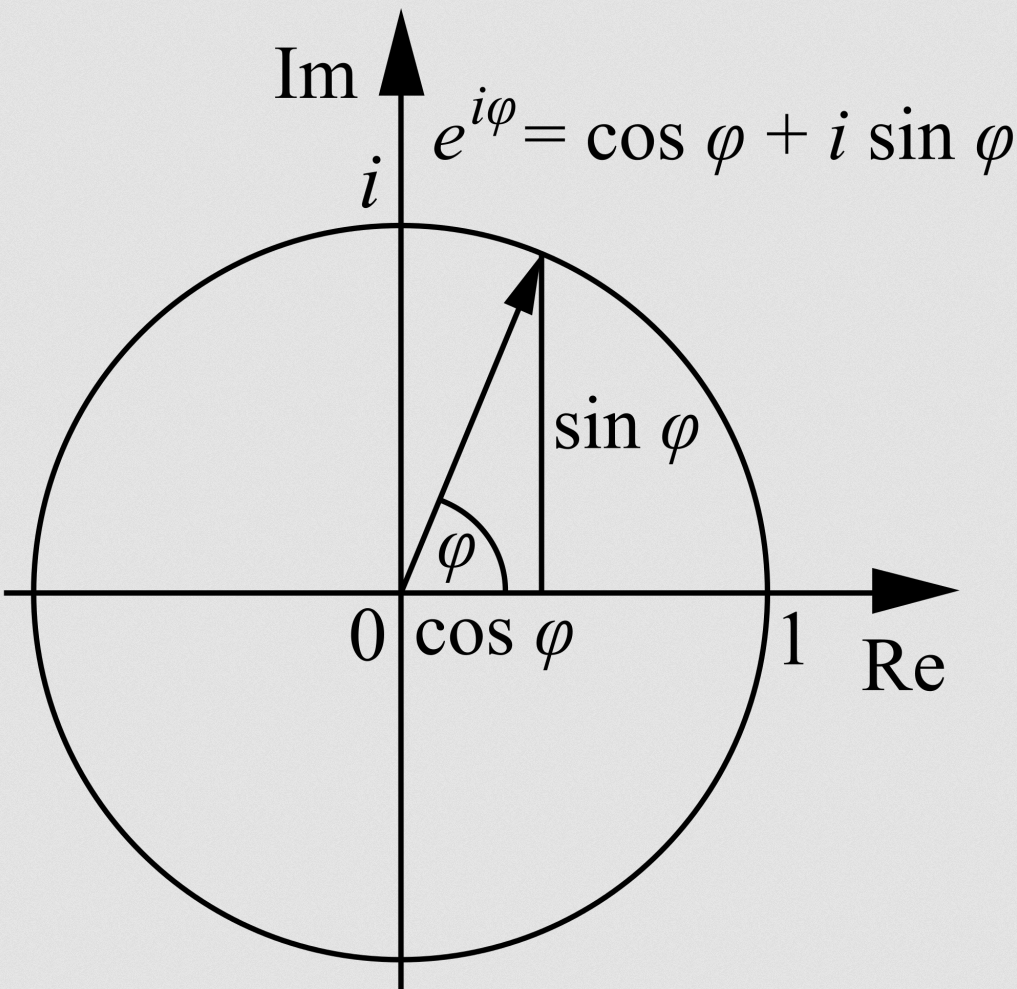

Since the square of 1 is 1, the coherence function is the same:

        
$${\left|\gamma_{\textrm{zx}} \left(\omega \right)\right|}^2 =\frac{{\left|S_{\textrm{yx}} \left(\omega \right)\right|}^2 \;}{S_y \left(\omega \right)S_{\mathrm{x}} \left(\omega \right)}$$


This means that a delay in the measurement does not effect the coherence function!

## [✔] ADSI Problem 4.9: MA(q) processes

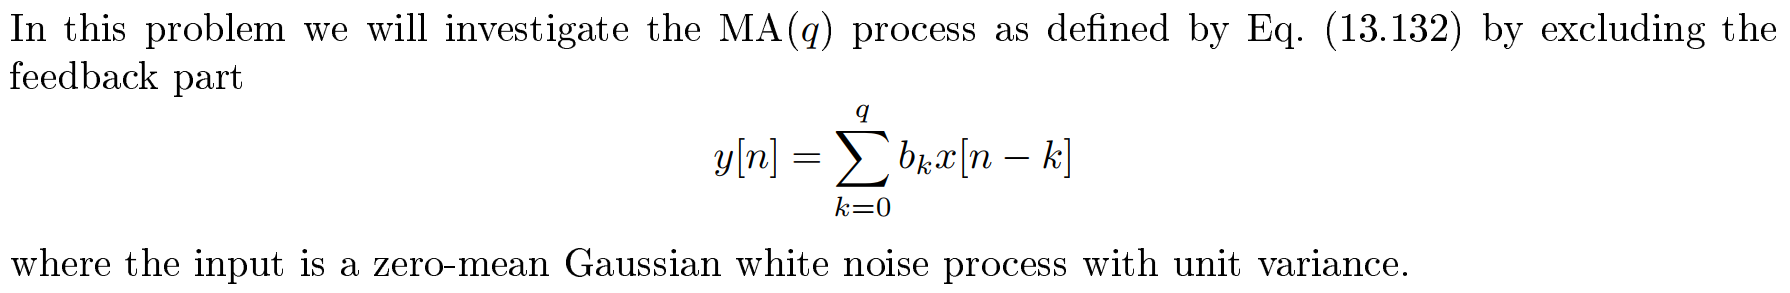

### 1) Write out the full expressions

The general $\mathrm{ARMA}\left(p,q\right)$is given by the difference equation:

        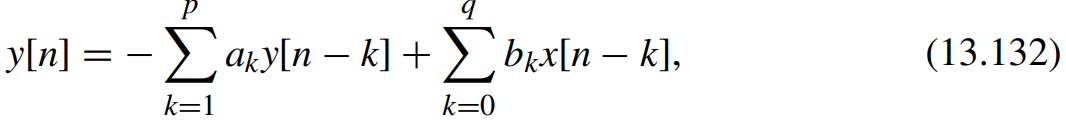

When the feedback part is excluded, all values of $a_k$ is set to zero, we are left with:

        
$$y\left\lbrack n\right\rbrack =\sum_{k=0}^q b_k \;x\left\lbrack n-k\right\rbrack$$


We can write out the full expressions for the difference processes as follows:

        
$$\mathrm{MA}\left(0\right)\;\;\to \;\;y\left\lbrack n\right\rbrack =b_0 \;x\left\lbrack n\right\rbrack$$
 

        
$$\mathrm{MA}\left(1\right)\;\;\to \;\;y\left\lbrack n\right\rbrack =b_0 \;x\left\lbrack n\right\rbrack +b_1 \;x\left\lbrack n-1\right\rbrack$$


        
$$\mathrm{MA}\left(2\right)\;\;\to \;\;y\left\lbrack n\right\rbrack =b_0 \;x\left\lbrack n\right\rbrack +b_1 \;x\left\lbrack n-1\right\rbrack +b_2 \;x\left\lbrack n-2\right\rbrack$$


        
$$\mathrm{MA}\left(3\right)\;\;\to \;\;y\left\lbrack n\right\rbrack =b_0 \;x\left\lbrack n\right\rbrack +b_1 \;x\left\lbrack n-1\right\rbrack +b_2 \;x\left\lbrack n-2\right\rbrack +b_3 \;x\left\lbrack n-3\right\rbrack$$


### 2) Calcute the autocorrelation for the MA processes

The autocorrelation function of a random process is defined as:

        
$$r_{\textrm{yy}} \left(\ell \right)=E\left\lbrack y\left(n\right)y\left(n-\ell \right)\right\rbrack$$


To compute the autocorrelation for the $\mathrm{MA}\left(0\right)$, just plug its difference equation into this equation:

        
$$r_{\textrm{yy}} \left(\ell \right)=E\left\lbrack b_0 \;x\left(n\right)\cdot b_0 \;x\left(n-\ell \right)\right\rbrack$$


        
$$r_{\textrm{yy}} \left(\ell \right)=b_0^2 E\left\lbrack x\left(n\right)\cdot x\left(n-\ell \right)\right\rbrack$$


        
$$r_{\textrm{yy}} \left(\ell \right)=b_0^2 \;r_{\mathrm{xx}} \left(\ell \right)$$
 

The autocorrelation of a white noise signal $w\left(n\right)$ is: $r_{\textrm{ww}} \left(\ell \right)=\sigma_w^2 \delta \left(\ell \right)$ where $\sigma_w^2$ is the signal's variance (see week 6 notes)

We are given that the input signal $x\left(n\right)$ is Gaussian white noise with unit variance.  This means $r_{\textrm{xx}} \left(\ell \right)=\delta \left(\ell \right)$

Therefore, the autocorrelation for MA(0) process is:

        
$$r_{\textrm{yy}} \left(\ell \right)=b_0^2 \;\delta \left(\ell \right)$$
 

The autocorrelation for the $\textrm{MA}\left(1\right)$ process is:

        
$$r_{\textrm{yy}} \left(\ell \right)=E\left\lbrack \left(b_0 \;x\left\lbrack n\right\rbrack +b_1 \;x\left\lbrack n-1\right\rbrack \right)\cdot \left(b_0 \;x\left\lbrack n-\ell \right\rbrack +b_1 \;x\left\lbrack n-\ell -1\right\rbrack \right)\right\rbrack$$


Multiply the two factors:

        
$$r_{\textrm{yy}} \left(\ell \right)=E\left\lbrack b_0^2 \;x\left\lbrack n\right\rbrack x\left\lbrack n-\ell \right\rbrack +b_0 b_1 x\left\lbrack n\right\rbrack x\left\lbrack n-\ell -1\right\rbrack +b_0 b_1 \;x\left\lbrack n-1\right\rbrack \;x\left\lbrack n-\ell \right\rbrack +b_1^2 x\left\lbrack n-1\right\rbrack x\left\lbrack n-\ell -1\right\rbrack \right\rbrack$$


Rearrange the coefficients:

        
$$r_{\textrm{yy}} \left(\ell \right)=E\left\lbrack b_0^2 \;x\left\lbrack n\right\rbrack x\left\lbrack n-\ell \right\rbrack +b_0 b_1 \left(x\left\lbrack n\right\rbrack x\left\lbrack n-\ell -1\right\rbrack +x\left\lbrack n-1\right\rbrack \;x\left\lbrack n-\ell \right\rbrack \right)+b_1^2 x\left\lbrack n-1\right\rbrack x\left\lbrack n-\ell -1\right\rbrack \right\rbrack$$


Split the expectation values and move constants outside $E\left\lbrack \cdot \right\rbrack$

        
$$r_{\textrm{yy}} \left(\ell \right)=b_0^2 \;E\left\lbrack x\left\lbrack n\right\rbrack x\left\lbrack n-\ell \right\rbrack \right\rbrack +b_0 b_1 \;E\left\lbrack \left(x\left\lbrack n\right\rbrack x\left\lbrack n-\ell -1\right\rbrack +x\left\lbrack n-1\right\rbrack \;x\left\lbrack n-\ell \right\rbrack \right)\right\rbrack +b_1^2 \;E\left\lbrack x\left\lbrack n-1\right\rbrack x\left\lbrack n-\ell -1\right\rbrack \right\rbrack$$


Split the expectation value in the second term:

        
$$r_{\textrm{yy}} \left(\ell \right)=b_0^2 \;E\left\lbrack x\left\lbrack n\right\rbrack x\left\lbrack n-\ell \right\rbrack \right\rbrack +b_0 b_1 \;\left(E\left\lbrack x\left\lbrack n\right\rbrack x\left\lbrack n-\ell -1\right\rbrack \right\rbrack +E\left\lbrack x\left\lbrack n-1\right\rbrack \;x\left\lbrack n-\ell \right\rbrack \right\rbrack \right)+b_1^2 \;E\left\lbrack x\left\lbrack n-1\right\rbrack x\left\lbrack n-\ell -1\right\rbrack \right\rbrack$$


Replace expectation values with autocorrelation functions:

        
$$r_{\textrm{yy}} \left(\ell \right)=b_0^2 \;r_{\mathrm{xx}} \left(\ell \right)+b_0 b_1 \;\left(r_{\mathrm{xx}} \left(\ell -1\right)+r_{\mathrm{xx}} \left(\ell +1\right)\right)+b_1^2 \;r_{\mathrm{xx}} \left(\ell \right)$$


Rearrange the terms

        
$$r_{\textrm{yy}} \left(\ell \right)=\left(b_0^2 \;+b_1^2 \right)r_{\textrm{xx}} \left(\ell \right)+b_0 b_1 \;\left(r_{\textrm{xx}} \left(\ell -1\right)+r_{\textrm{xx}} \left(\ell +1\right)\right)$$


As before $r_{\textrm{xx}} \left(\ell \right)=\delta \left(\ell \right)$ because the input signal is a white noise with unit variance. Substitute:

        
$$r_{\textrm{yy}} \left(\ell \right)=\left(b_0^2 \;+b_1^2 \right)\delta \left(\ell \right)+b_0 b_1 \;\left(\delta \left(\ell -1\right)+\delta \left(\ell +1\right)\right)$$


The autocorrelation for an MA(2) process is:

        
$$r_{\mathrm{yy}} \left(\ell \right)=\left(b_0^2 +b_1^2 +b_2^2 \right)\delta \left(\ell \right)+\left(b_0 b_1 +b_1 b_2 \right)\delta \left(\ell +1\right)+\left(b_0 b_1 +b_1 b_2 \right)\delta \left(\ell -1\right)+b_0 b_2 \delta \left(\ell +2\right)+b_0 b_2 \delta \left(\ell -2\right)$$


The autocorrelation for an MA(3) process is:

        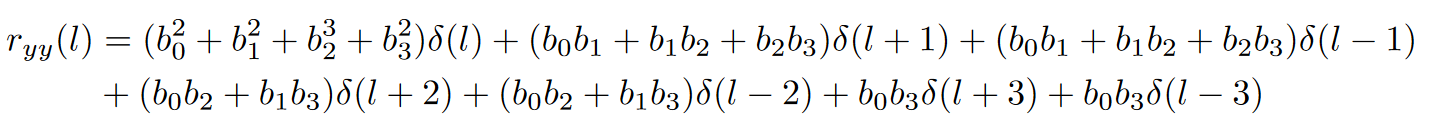

### 3) Calculate power density spectra

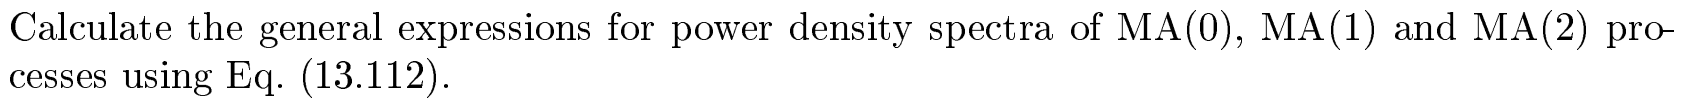

The power spectral density (PSD) is defined as:

        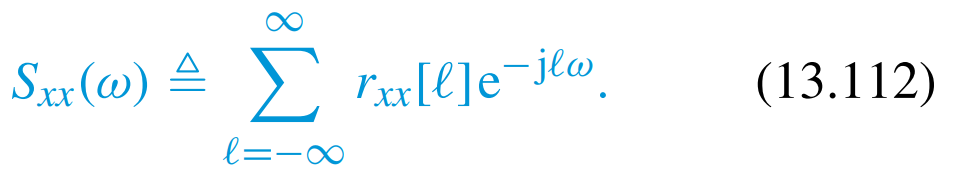

In 2) we found that the autocorrelation for $\mathrm{MA}\left(0\right)$ is $r_{\textrm{yy}} \left(\ell \right)=b_0^2 \;\delta \left(\ell \right)$, so plug it in this PSD formula:

        
$$S_{\textrm{yy}}^{\mathrm{MA}\left(0\right)} \left(\omega \right)=\sum_{\ell =-\infty }^{\infty } r_{\textrm{yy}} \left(\ell \right)e^{-\j \ell \omega } =\sum_{\ell =-\infty }^{\infty } b_0^2 \;\delta \left(\ell \right)e^{-\j \ell \omega }$$


We notice that $r_{\textrm{yy}} \left(\ell \right)$ has non-zero value only when $\ell =0$. Therefore, the terms for when $\ell \not= 0$ are zero. We can, therefore, remove the infinite sum. Since $\delta \left(0\right)=1$and $e^{-\j 0\omega } =1$, we have:

        
$$S_{\textrm{yy}}^{\mathrm{MA}\left(0\right)} \left(\omega \right)=b_0^2 \;\delta \left(0\right)e^{-\j 0\omega } =b_0^2 \cdot 1\cdot 1=b_0^2$$


We do similar computation to find the power density spectrum of MA(1) process. 

In 2) we found that the autocorrelation for MA(1) is:

        
$$r_{\textrm{yy}} \left(\ell \right)=\left(b_0^2 \;+b_1^2 \right)\delta \left(\ell \right)+b_0 b_1 \;\left(\delta \left(\ell -1\right)+\delta \left(\ell +1\right)\right)$$


There are three non-zero values of the autocorrelation function so the infinite sum has only three terms

        
$$S_{\textrm{yy}}^{\textrm{MA}\left(1\right)} \left(\omega \right)=\sum_{\ell =-\infty }^{\infty } \left(\left(b_0^2 \;+b_1^2 \right)\delta \left(\ell \right)+b_0 b_1 \;\left(\delta \left(\ell -1\right)+\delta \left(\ell +1\right)\right)\right)e^{-\j \ell \omega }$$


There are three non-zero values of the autocorrelation function so the infinite sum has only three terms:

- When $\ell =0$:   $\left(b_0^2 \;+b_1^2 \right)\delta \left(0\right)e^{-j\left(0\right)\omega } =\left(b_0^2 \;+b_1^2 \right)\cdot 1\cdot 1=\left(b_0^2 \;+b_1^2 \right)$

- When $\ell =-1$:  $b_0 b_1 \;\delta \left(0\right)e^{-j\left(-1\right)\omega } =b_0 b_1 \;\left(1\right)e^{j\omega } =b_0 b_1 \;e^{j\omega }$

- When $\ell =1$:     $b_0 b_1 \;\delta \left(0\right)e^{-j\left(1\right)\omega } =b_0 b_1 \;\left(1\right)e^{-j\omega } =b_0 b_1 \;e^{-j\omega }$

Therefore, we have:

        
$$S_{\textrm{yy}}^{\textrm{MA}\left(1\right)} \left(\omega \right)=\left(b_0^2 \;+b_1^2 \right)+b_0 b_1 e^{j\omega } +b_0 b_1 e^{-j\omega }$$


        
$$S_{\textrm{yy}}^{\textrm{MA}\left(1\right)} \left(\omega \right)=\left(b_0^2 \;+b_1^2 \right)+b_0 b_1 \left(e^{j\omega } +e^{-j\omega } \right)$$


Since $\mathrm{cos}\left(\theta \right)=\frac{1}{2}\left(e^{j\theta } +e^{-j\theta } \right)$ and $2\cdot \mathrm{cos}\left(\theta \right)=e^{j\theta } +e^{-j\theta }$, we write:

        
$$S_{\textrm{yy}}^{\textrm{MA}\left(1\right)} \left(\omega \right)=\left(b_0^2 \;+b_1^2 \right)+2b_0 b_1 \mathrm{cos}\left(\omega \right)$$


In similar fashion, the PSD of $\mathrm{MA}\left(2\right)$ is:

        
$$S_{\textrm{yy}}^{\textrm{MA}\left(2\right)} \left(\omega \right)=\left(b_0^2 \;+b_1^2 +b_2^2 \right)+2\left(b_0 b_1 +b_1 b_2 \right)\cos \left(\omega \right)+2b_0 b_1 \cos \left(2\omega \right)$$


### 4) Plot the power density spectra given coefficients

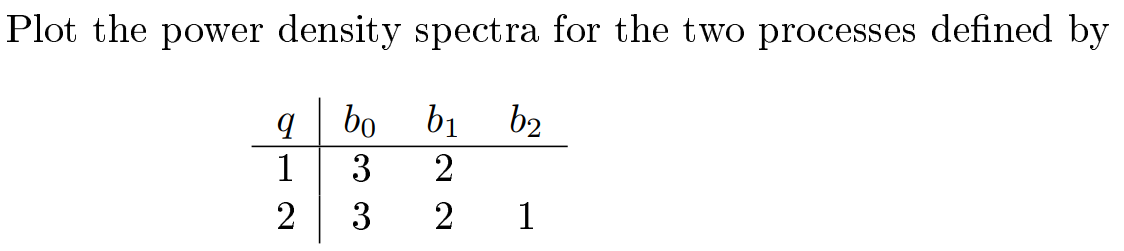

We are given the coefficients for $S_{\textrm{yy}}^{\textrm{MA}\left(1\right)} \left(\omega \right)$and $S_{\textrm{yy}}^{\textrm{MA}\left(2\right)} \left(\omega \right)$. We use results from 3) to plot the power density spectra for the two processes.

        
$$S_{\textrm{yy}}^{\textrm{MA}\left(1\right)} \left(\omega \right)=\left(b_0^2 \;+b_1^2 \right)+2b_0 b_1 \cos \left(\omega \right)$$


        
$$S_{\textrm{yy}}^{\textrm{MA}\left(2\right)} \left(\omega \right)=\left(b_0^2 \;+b_1^2 +b_2^2 \right)+2\left(b_0 b_1 +b_1 b_2 \right)\cos \left(\omega \right)+2b_0 b_1 \cos \left(2\omega \right)$$


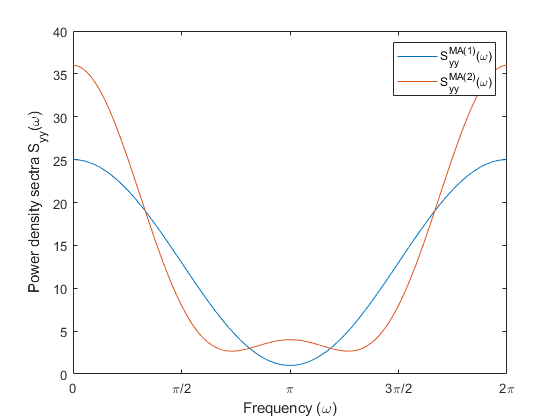

w=0:0.001:2*pi;

% Define the coefficients
b0 = 3; b1 = 2; b2 = 1;

% The power desnity spectrum for the MA(1) process
S1 = (b0^2 + b1^2) + 2*b0*b1*cos(w);
% The power desnity spectrum for the MA(2) process
S2 = (b0^2 + b1^2 + b2^2) + 2*(b0*b1 + b1*b2)*cos(w) + 2*b0*b2*cos(2*w);

plot(w, S1, w, S2);
legend('S_{yy}^{MA(1)}(\omega)','S_{yy}^{MA(2)}(\omega)');
xlabel('Frequency (\omega)');
ylabel('Power density sectra S_{yy}(\omega)');
set(gca,'XTick',0:pi/2:2*pi) 
set(gca,'XTickLabel',{'0','\pi/2','\pi','3\pi/2','2\pi'})
xlim([0,2*pi])

## [✔] ADSI Problem 4.10: MA processes and phase properties

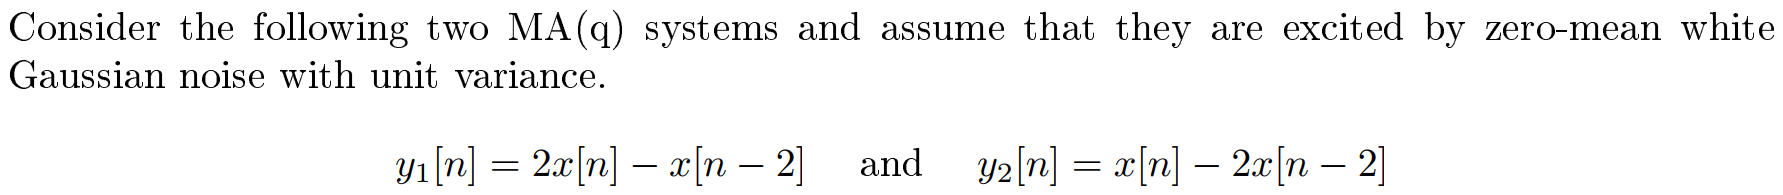

### 1) What is the order q of the processes

The order $q$ of an $\mathrm{MA}\left(q\right)$ process is given by the longest delay, i.e., $x\left\lbrack n-q\right\rbrack$. Therefore, both systems are of order 2.

### 2) Compare the phase properties of the two systems

To determine the phase properties of a system, we need to plot where its the zeros are located in relation to the unit circle in a zero-pole plot. If all zeros are located within the unit circle, then we have a minimum-phase system.

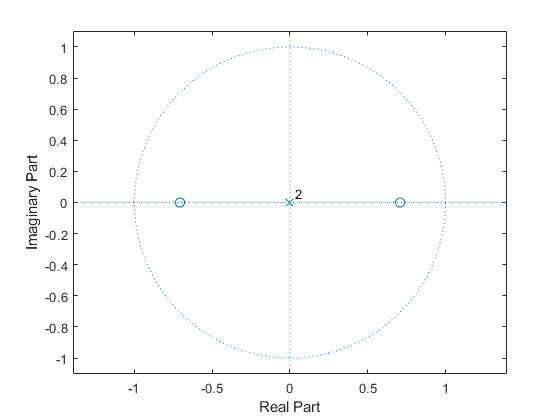

h1 = [2, 0, -1]; % Impulse response for y1[n]
zplane(h1);

From the zero-pole plot, we observe that all the zeros are within the unit circle. Therefore, we can conclude that the system $y_1 \left\lbrack n\right\rbrack$ is a minimum-phase.

Let us make the zero-plot for the system $y_2 \left\lbrack n\right\rbrack =x\left\lbrack n\right\rbrack -2x\left\lbrack n-2\right\rbrack$

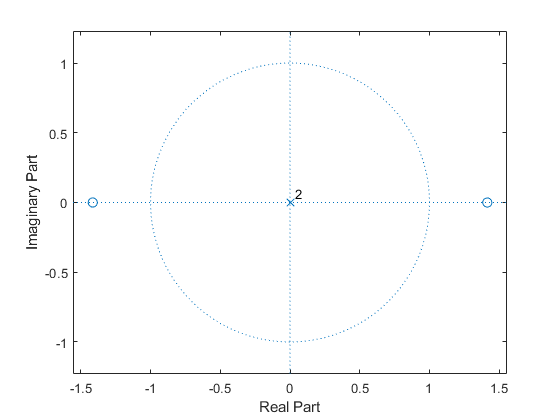

h2 = [1, 0, -2]; % Impulse response for y2[n]
zplane(h2);

Since both zeros are outside the unit circle, we can conclude the system $y_2 \left\lbrack n\right\rbrack$ is a maximum-phase system.

## ADSI Problem 4.12: MA(q) spectral estimation

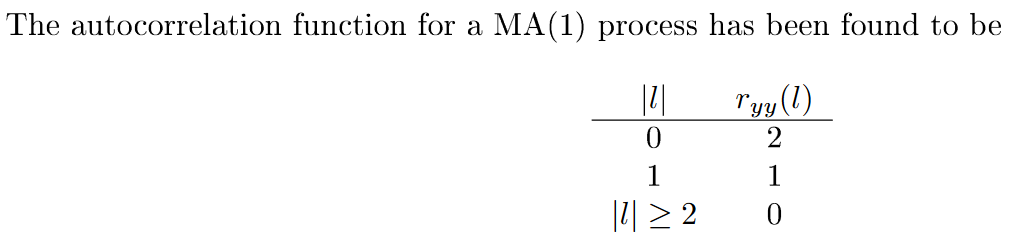

### 1) Plot the power density spectrum

### 2) Calculate the model parameters

## ADSI Problem 4.15: AR(p) signal modelling

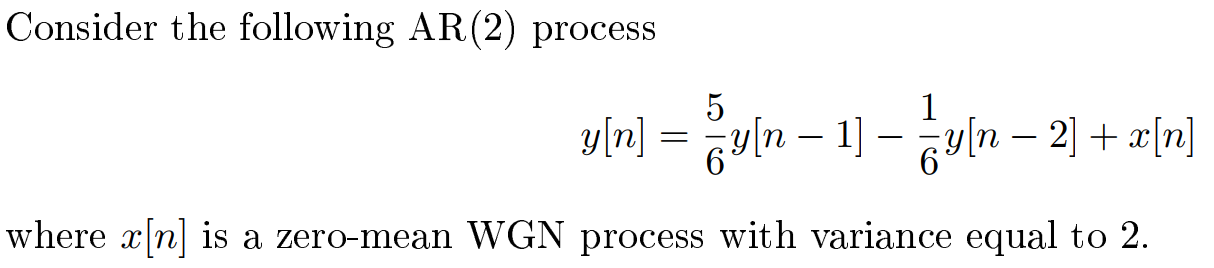

### 1) Calculate and plot the theoretical power density spectrum.

### 2) Create a 1024 samples long realization of the process and calculate the autocorrelation

### 3) Fit AR(4) and AR(6) models

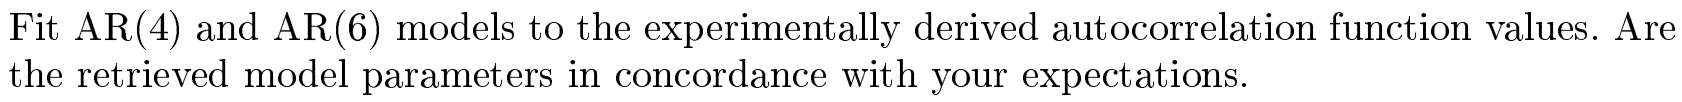

### 4) Compare the power density spectra of the AR(4) and AR(6) model with the result from question 1.  

## ADSI Problem 4.17: Signal modelling of speech

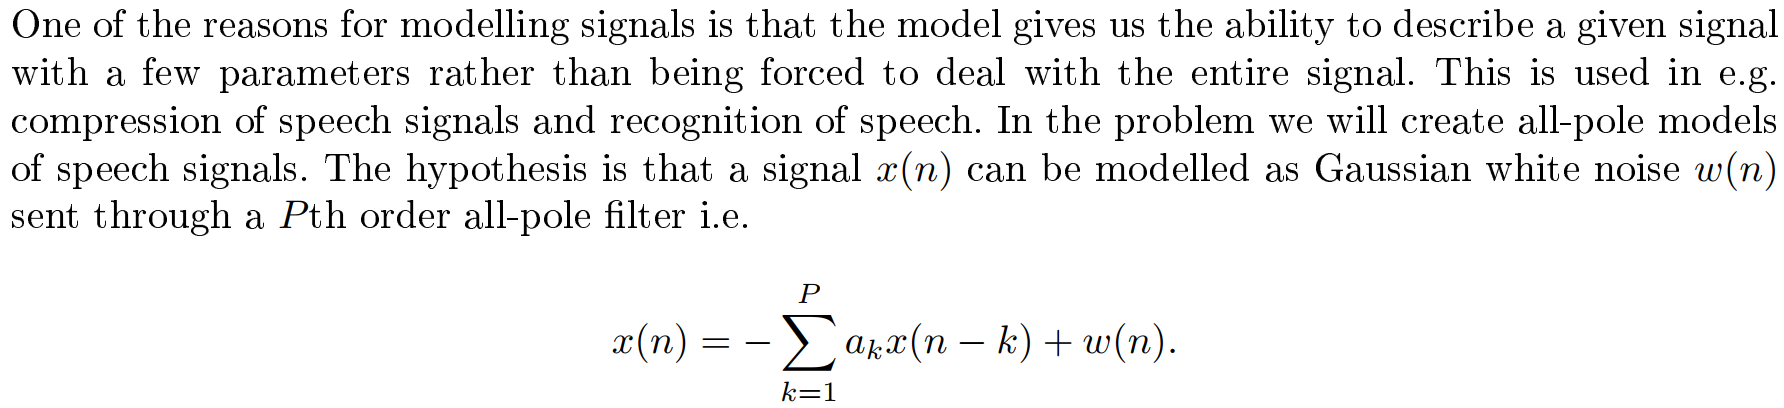

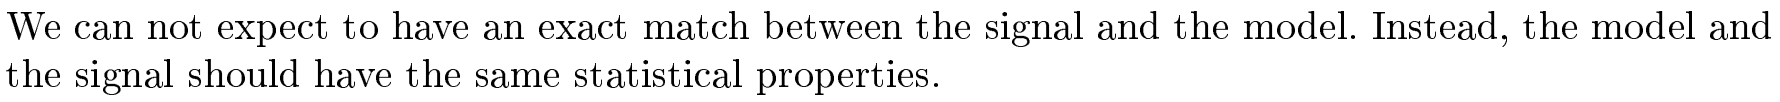

1) Record your voice

### 2) Can a short sequence of your signal be described with an AR(1) model?

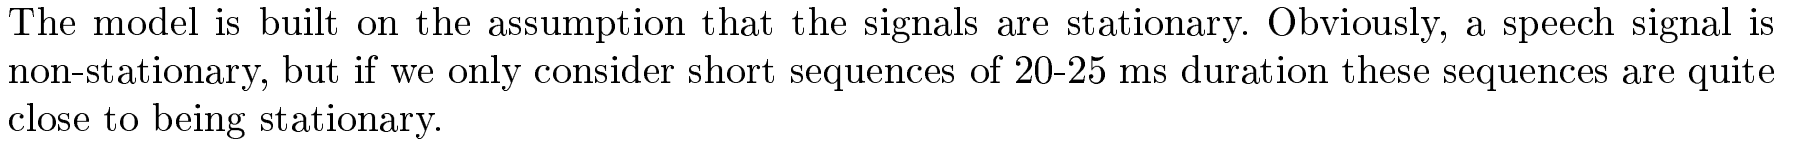

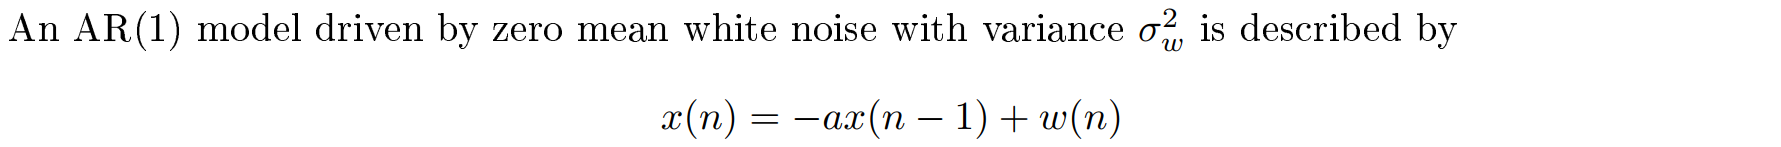

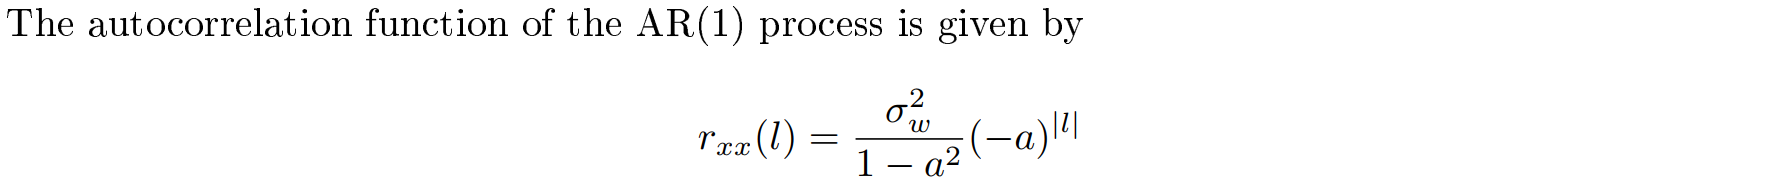

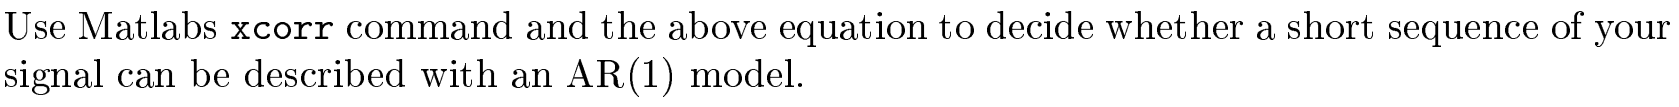

### 3) Create an AR(2) model using Yule-Walter equations (13.149)

### 4) Whiten your speech signal

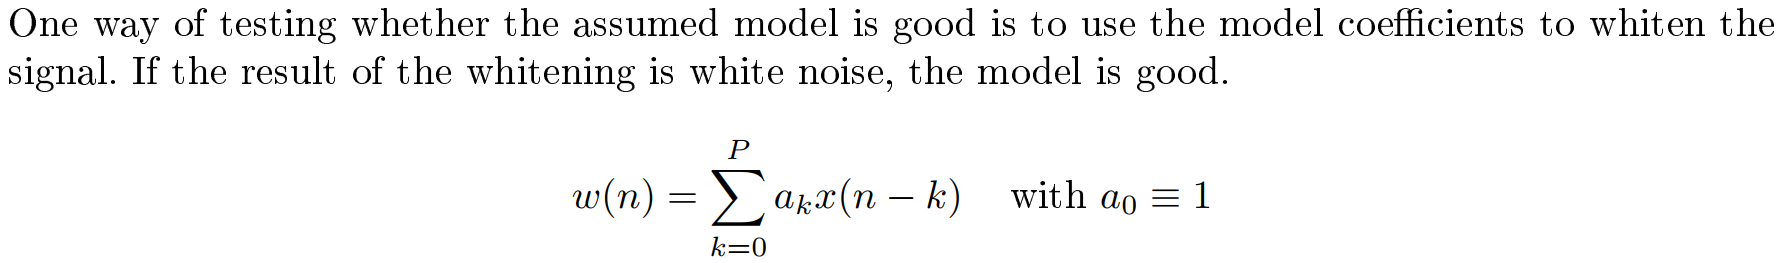

### 5) Increase the order of the all-pole filter

### 6) Repeat the above questions for voiced, unvoiced and noisy speech signals.